clc;clear;close all;

% read the file
run = readmatrix('run.csv');
sleep = readmatrix("sleep.csv");

% normalize and filtering
process_run = process_ppg(run);
process_sleep = process_ppg(sleep);

% Process2
run_PBV = process_PBV(process_run); 
run_POS = process_POS(process_run);
run_CHROM = process_CHROM(process_run);

sleep_PBV = process_PBV(process_sleep);
sleep_POS = process_POS(process_sleep);
sleep_CHROM = process_CHROM(process_sleep);

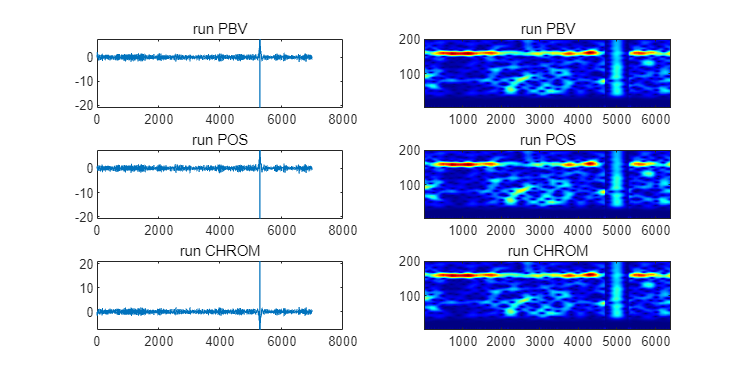

% plot
fs = 60;
[run_PBV_spc, ~] = spec(run_PBV,fs);
[sleep_PBV_spc, ~] = spec(sleep_PBV, fs);
[run_POS_spc, ~] = spec(run_POS, fs);
[sleep_POS_spc, ~] = spec(sleep_POS, fs);
[run_CHROM_spc, ~] = spec(run_CHROM, fs);
[sleep_CHROM_spc, ~] = spec(sleep_CHROM, fs);

figure, set(gcf, 'Position', [100 100 2000 1000]); colormap('jet');
subplot(3,2,1);
plot(run_PBV);
title('run PBV')
subplot(3,2,2);
imagesc(run_PBV_spc(1:200,:)); set(gca,'YDir','normal');
title('run PBV')
subplot(3,2,3);
plot(run_POS);
title('run POS')
subplot(3,2,4);
imagesc(run_POS_spc(1:200,:)); set(gca,'YDir','normal');
title('run POS')
subplot(3,2,5);
plot(run_CHROM);
title('run CHROM')
subplot(3,2,6);
imagesc(run_CHROM_spc(1:200,:)); set(gca,'YDir','normal');
title('run CHROM')

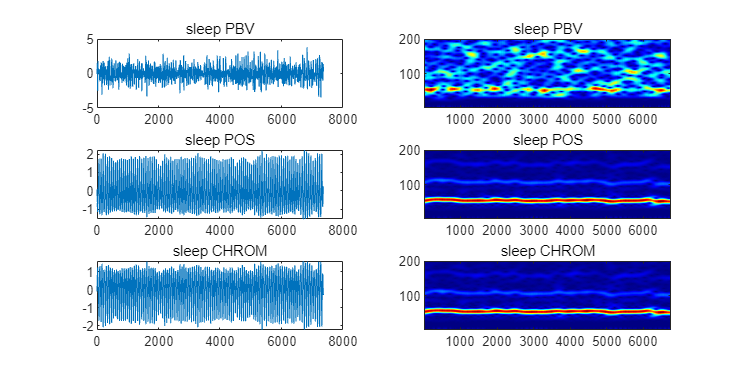

figure, set(gcf, 'Position', [100 100 2000 1000]); colormap('jet');
subplot(3,2,1);
plot(sleep_PBV);
title('sleep PBV')
subplot(3,2,2);
imagesc(sleep_PBV_spc(1:200,:)); set(gca,'YDir','normal');
title('sleep PBV')
subplot(3,2,3);
plot(sleep_POS);
title('sleep POS')
subplot(3,2,4);
imagesc(sleep_POS_spc(1:200,:)); set(gca,'YDir','normal');
title('sleep POS')
subplot(3,2,5);
plot(sleep_CHROM);
title('sleep CHROM')
subplot(3,2,6);
imagesc(sleep_CHROM_spc(1:200,:)); set(gca,'YDir','normal');
title('sleep CHROM')

function [spc, rate] = spec(signal, fps)
% Input: pulse - 1xN pulse signal
% fps - 1x1 camera frame rate
% Output: spc - 1xM pulse specctrogram
% hr - 1xM heart rate signal
% define parameter
L = fps * 10;
S = zeros(size(signal,2)-L+1,L);
for idx = 1:size(signal,2)-L+1
p = signal(1,idx:idx+L-1);
S(idx,:) = (p-mean(p))/(eps+std(p));
end
S = S-repmat(mean(S,2),[1,L]);
S = S .* repmat(hann(L)',[size(S,1),1]);
S = abs(fft(S,fps*60,2));
spc = S(:,1:fps*60/2)';
[~, rate] = max(spc,[],1);
rate = rate - 1;
end

function Filtered_RGB = process_ppg(data)
R = data(:,2);
G = data(:,3);
B = data(:,4);

R_norm = R/mean(R)-1;
G_norm = G/mean(G)-1;
B_norm = B/mean(B)-1;

%Filter
fs = 60;
nyq = 0.5 * fs;
low = 0.6 / nyq;
high = 4 / nyq;
[b, a] = butter(4, [low, high], 'bandpass');
filtered_R = filtfilt(b, a, R_norm);
filtered_G = filtfilt(b, a, G_norm);
filtered_B = filtfilt(b, a, B_norm);
filtered_RGB = [filtered_R, filtered_G, filtered_B];
Filtered_RGB = filtered_RGB';
end

function  PBV = process_PBV(signal)
param.pbv = [0.3, 0.9, 0.5]; % 1×3 size
% PBV = zeros(size(signal,1), size(signal,2));
p = param.pbv * pinv(signal * signal') * signal;
PBV(:) = (p-mean(p))/std(p);
end

function POS = process_POS(signal)
% POS = zeros(size(signal,1), size(signal,2));
s = [0, 1, -1; -2, 1, 1] * signal; % POS projection system
p = [1, std(s(1,:))/std(s(2,:))] * s; % plus
POS(:) = (p-mean(p))/std(p);
end

function CHROM = process_CHROM(signal)
% CHROM = zeros(size(signal,1), size(signal,2));
s = [3, -2, 0; 1.5, 1, -1.5] * signal;
p = [1, -std(s(1,:))/std(s(2,:))] * s; % minus
CHROM(:) = (p-mean(p))/std(p);
end